clear

% Read img file
img = imread("../db/DB1/db1_02.jpg")

img = 536×399×3 uint8 array
img(:,:,1) =

   197   196   194   193   194   196   196   194   195   196   197   198   198   198   199   200   199   200   201   202   202   201   201   202   201   202   202   203   203   203   202   201   202   200   199   201   200   199   203   199   203   203   202   201   200   199   200   200   202   202   202   203   203   202   203   205   203   208   210   207   204   205   205   204   205   206   206   205   204   204   206   207   208   208   207   207   207   207   206   206   206   204   203   203   204   206   206   206   208   205   205   204   203   204   206   204   207   206   207   207   205   206   208   207   205   205   205   205   208   208   209   208   207   206   206   207   207   207   210   213   208   205   205   208   209   208   209   211   208   208   209   208   208   208   208   209   211   209   209   211   209   205   205   209   210   209   209   209   209   209   209   208   209   210   208   206   207   210   211   2

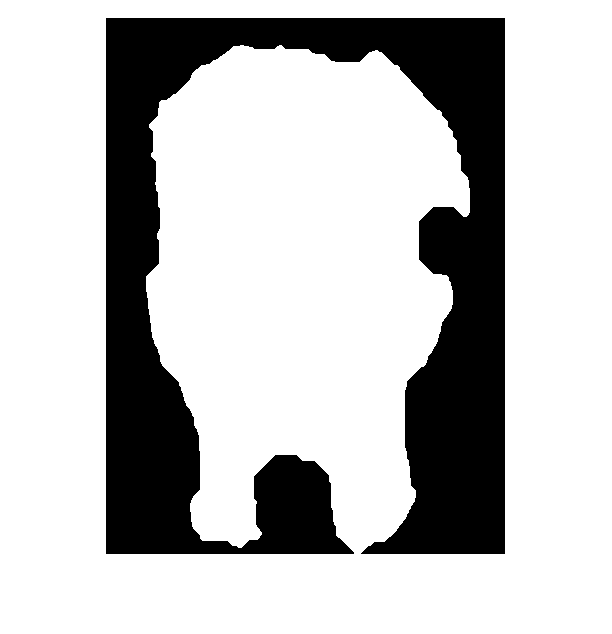


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.0817    0.0817    0.0817    0.0823    0.0817    0.0821    0.0821    0.0821    0.0821    0.0821    0.0821    0.0826    0.0826    0.0821    0.0821    0.0814    0.0821    0.0814    0.0809    0.0804    0.0804    0.0804    0.0804    0.0813    0.0820    0.0816    0.0816    0.0816    0.0823    0.0827    0.0827    0.0821    0.0814    0.0800    0.0807    0.0807    0.0807    0.0807    0.0814    0.0814    0.0814    0.0814    0.0807    0.0807    0.0807    0.0807    0.0805    0.0805    0.0818    0.0818
    0.0817    0.0817    0.0817    0.0817    0.0821    0.0821    0.0821    0.0821    0.0821    0.0821    0.0826    0.0826    0.0826    0.0821    0.0821    0.0814    0.0821    0.0814    0.0809    0.0813    0.0813    0.0813    0.0813    0.0813    0.0820    0.0825    0.0820    0.0820    0.0827    0.0827    0.0827    0.0821    0.0807    0.0807    0.0807    0.0807    0.0807    0.0807    0.0814    0.0814    0.0814    0.0814    0.0807    0.0807    0.0807    0.0807    0.0805    0.0805    0.0818  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 536×399 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

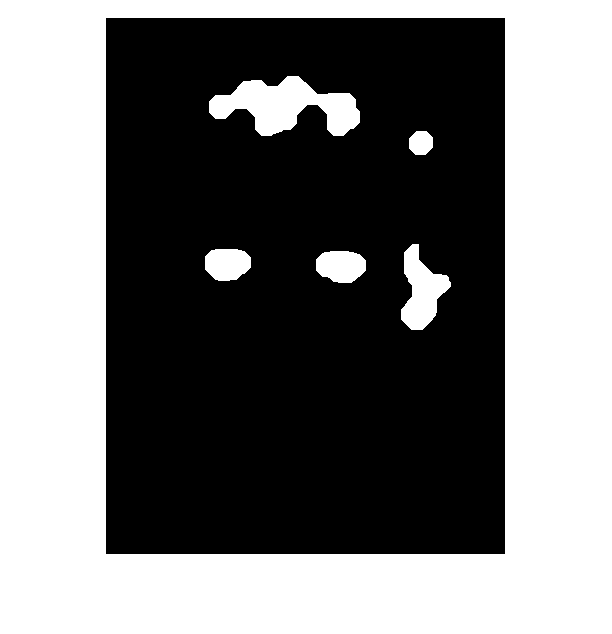



imshow(eye_mask);


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 292

y = 327

[indexX,indexY] = eye_index(eye_mask)

indexX =   121.8474  235.5544  316.1839  315.5000


indexY =   246.5619  248.6463  273.4889  125.5000



% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    40.9205   80.5575  116.8129  183.7451


sorted_mid_indices =      2     1     3     4



% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      2     1


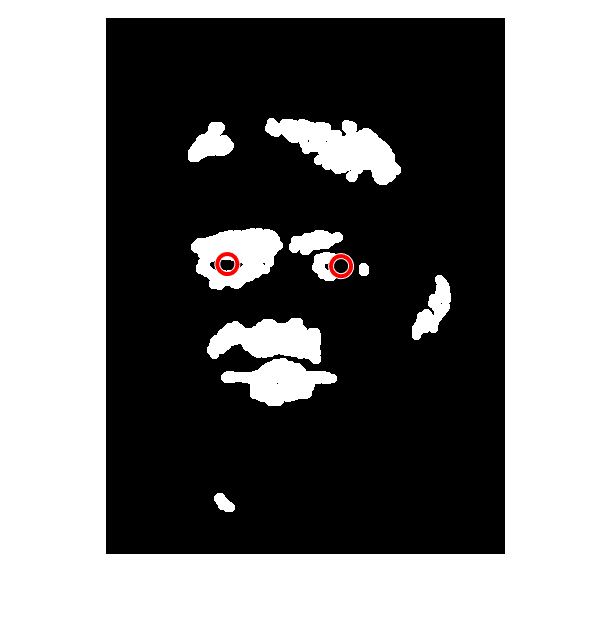

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

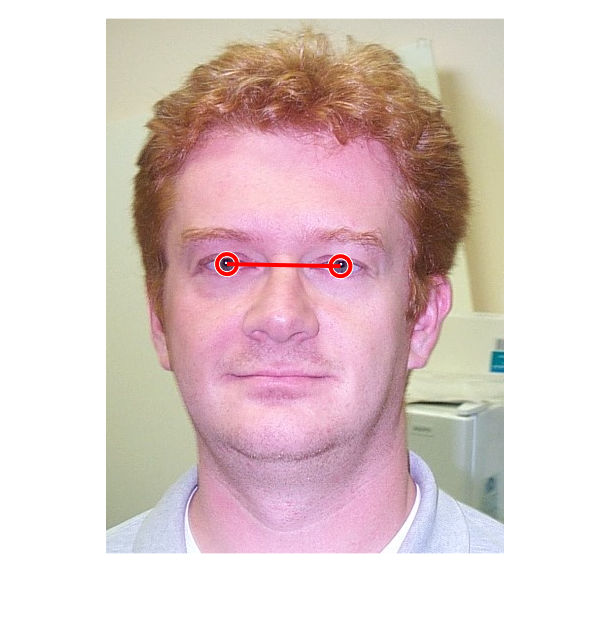


eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

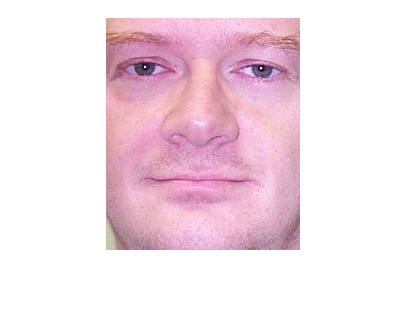


% Definiera antal pixlar från munnen neråt, ögonen uppåt, samt ögonen utåt
pixels_down_from_eyes = 180; % Antal pixlar från munnen neråt
pixels_up_from_eyes = 50;    % Antal pixlar från ögonen uppåt
pixels_sideways_from_eyes = 40; % Antal pixlar från ögonen utåt

% Beräkna koordinaterna för den nya rektangeln som inkluderar ansiktet
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Säkerställ att det inte går utanför bildens gränser
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Avrunda koordinaterna för att säkerställa att de är heltal
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Beskär bilden baserat på de beräknade koordinaterna
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);

% Visa den beskurna bilden
figure;
imshow(cropped_img);


% Definiera önskad storlek för alla beskurna bilder
desired_height = 200;
desired_width = 300;

% Beräkna storleken på den nuvarande beskurna bilden
current_height = size(cropped_img, 1);
current_width = size(cropped_img, 2);

% Beräkna hur mycket padding som behövs på höjden och bredden för att nå önskad storlek
pad_height = max(desired_height - current_height, 0);
pad_width = max(desired_width - current_width, 0);

% Beräkna hur mycket padding som ska läggas till på toppen, botten, vänster och höger
pad_top = floor(pad_height / 2);
pad_bottom = ceil(pad_height / 2);
pad_left = floor(pad_width / 2);
pad_right = ceil(pad_width / 2);

% Använd padarray för att lägga till padding och uppnå önskad storlek
padded_img = padarray(cropped_img, [pad_top, pad_left], 0, 'pre')

padded_img = 232×247×3 uint8 array
padded_img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   218   218   216   221   225   225   224   230   230   230   232   234   236   238   240   241   240   238   236   236   238   237   236   235   242   245   245   245   243   241   243   249   246   247   248   248   246   243   245   244   248   252   251   247   245   248   252   247   246   249   245   250   246   249   248   231   244   245   255   252   255   245   239   249   245   235   250   255   254   255   251   244   251   253   255   251   249   254   250   247   252   253   249   248   252   251   250   248   245   244   245   250   252   254   251   252   249   245   246   254   255   254   253   248  

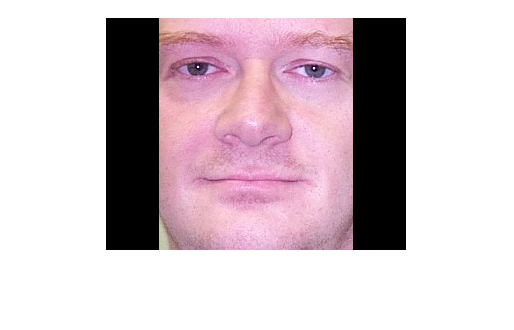

padded_img = padarray(padded_img, [pad_bottom, pad_right], 0, 'post');

% Visa den beskurna och anpassade bilden till önskad storlek
figure;
imshow(padded_img);